# Lecture 7 Diffraction-Limited 3D Imaging

## 1. 3D point spread function

### 1.1 Gaussian beam propagation

In the previous lecture we introduced the coherent 2D point spread function (PSF) $f_0 \left(x,y\right)$. We have also discussed using diffraction theory to calculate the field and intensity profile along the propagation direction. 

Particularly, we showed the beam profile on the defocusd plane $f_z \left(x,y\right)$. Stacking the 2D field profiles, treating the defocus as a variable, we get the 3D field profile $f\left(x,y,z\right)$.

Gaussian beam 3D profiles will be discussed in this section, because it is a good approximation for the beam profile from a coherent light source and it has a simple analytical expression.

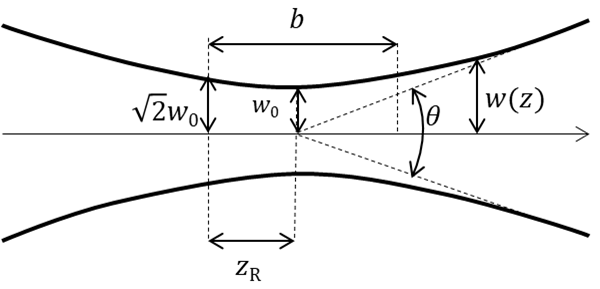

**ILL. 1.1 ***Gaussian beam parameters*

Using the Gaussian beam with beam waist $w_0$, and a zero constant phase at the waist, the field can be expressed as:


$$E\left(\rho ,0\right)=E_0 e^{-\frac{\rho^2 }{w_0^2 }}$$


The angular spectrum at the beam waist is a 2D Fourier transform in radial coordinate.


$$\left\lbrace E\left(\rho ,0\right)\right\rbrace \overset{2D\;\textrm{FT}}{\longrightarrow} E\left({\mathbf{k}}_{\;\rho } ,0\right)=\pi E_0 w_0^2 e^{-\frac{w_0^2 k_{\rho }^2 }{4}}$$


${\mathbf{k}}_{\rho }$ is the spatial frequency in the radial coordinates, and wave number $k=\frac{2\pi n}{\lambda }$, $\lambda \;$is the wavelength, $n$ is the refractive index.


$$k^2 =k_{\rho }^2 +k_z^2$$


Using Fresnel approximation, $k_z =k-\frac{k_{\rho }^2 }{2k}$, the field on the plane at $z$, the angular spectrum is


$$E\left({\mathbf{k}}_{\rho } ,z\right)=E\left({\mathbf{k}}_{\rho } ,0\right)e^{{\textrm{ik}}_z z} =\pi E_0 w_0^2 e^{-\frac{w_0^2 k_{\rho }^2 }{4}} e^{\textrm{ikz}} \times e^{-i\frac{k_{\rho }^2 }{2k}z}$$


The field at z plane is:


$$\left\lbrace E\left(k_{\rho } ,0\right)\right\rbrace \overset{2D\;\textrm{IFT}}{\longrightarrow} E\left(\rho ,z\right)$$


Here we will not go through the detailed derivation, but the analytical expression of the electric field at distance $z$ is


$$E\left(\rho ,z\right)=E_0 \frac{w_0 }{w\left(z\right)}e^{\frac{-\rho^2 }{{w\left(z\right)}^2 }} \times e^{\textrm{ikz}} \times e^{\textrm{ik}\frac{\rho^2 }{R\left(z\right)}} \times e^{i\eta \;\left(z\right)}$$


Where $w\left(z\right)=w_0 \sqrt{1+\frac{z^2 }{z_R^2 }}$ is the beam diameter, the constant $z_R =\frac{k}{2}w_0^2$ is called the Rayleigh length. 

$R\left(z\right)$ is the wavefront radius, and $\eta \left(z\right)=\tan^{-1} \left(\frac{z}{z_R }\right)$is called the Gouy phase shift. We define the divergence angle as $\theta =\frac{2w_0 }{z_R }$. 

***Example 1.1***

Gaussian beam propagation.

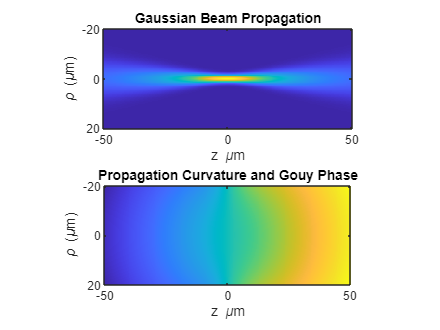

w0 = 1.5; % beam width [unit: um]
lambda = 0.632; % wavelength [unit: um]
n = 1; % refractive index of the medium
k = 2*pi*n/lambda; % wavenumber
zR = pi*w0^2*n/lambda; % Rayleigh length
n_rho = 128; % number of pixels in lateral direction
nz = 256; % number of pixels in axial direction
rho = linspace(-20,20,n_rho); % lateral radial coordinate
z = linspace(-50,50,nz); % axial coordinate
[R,Z] = ndgrid(rho,z);
e0 = 1; % peak electric field amplitude at beam waist

Wz = w0*sqrt(1+(Z./zR).^2);  %beam diameter
Rz = (Z.^2+zR^2)./Z; %radius of wavefront curvature
Amp = e0*w0./Wz.*exp(-R.^2./Wz.^2);
Phi = k.*Z + k.*R.^2./(2.*Rz) - atan(Z./zR); % propagation curvature and Gouy phase

figure;
set(gcf,'Position', [100 100 400 300])
subplot(211)
imagesc(z,rho,Amp) 
title('Gaussian Beam Propagation')
axis tight; axis equal;
xlabel('z \mum'); ylabel('\rho (\mum)');

subplot(212)
%imagesc(z,r,wrapTo2Pi(Phi))
imagesc(z,rho,Phi)
title("Propagation Curvature and Gouy Phase")
axis tight; axis equal;
xlabel('z \mum'); ylabel('\rho (\mum)');

### **1.2 Incoherent 3D imaging**

Compared to the 2D case, 3D coherent imaging is more complicated due to the interference along the depth direction. Here we discuss an idealized 3D incoherent imaging scenario: Each point in the object space creates the same 3D point spread function in image volume and follows intensity superposition.

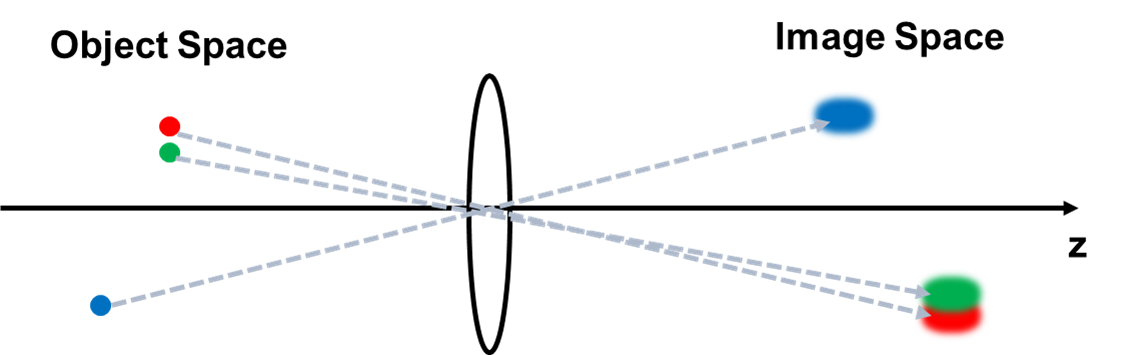

**ILL. 1.2 ***Idealized incoherent imaging scenerio*

#### 1.2.1 3D incoherent PSF

In Section 1.1, we have quantitatively discussed the 3D distribution using the Gaussian beam. Following the assumption of a circular aperture of a diffraction limited imaging system, using scalar diffraction theory, we can also calculate the 3D field distribution in the focusing volume. The 3D PSF of an ideal lens is therefore the corresponding 3D intensity distribution. However, unlike the Gaussian beam, the distribution does not have a simple analytical form.

From the previous section for 2D PSF, we know that at focus the incoherent PSF is 


$$h\left(\rho ,z=0\right)$$


Using Fresnel approximation, the on-axis intensity can be derived to be:


$$h\left(0,z\right)\propto{\textrm{sinc}}^2 \left(\frac{\pi }{4{\rho_a }^2 k}z\right)$$
 

***Example 1.2***

Compare the axial PSF to the analytical PSF (the on-axis intensity derived in 1.2.1).

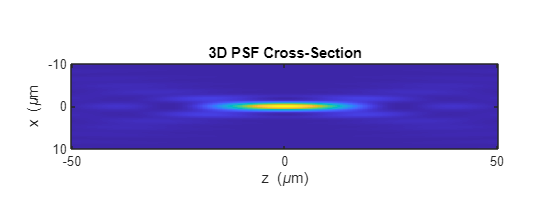

% unit in um
lambda=0.632;% the wavelength [unit: um]
NA = 0.22; % numerical aperture
% pixels on the x, y dimension
nx=128;
ny=128;
nz=256;
x=linspace(-10,10,nx);
y=linspace(-10,10,ny);
z=linspace(-50,50,nz);
%[X,Y]=ndgrid(x,y);

k=2*pi/lambda;
rho_a = lambda/(2*NA); % freqency half-bandwidth
kx=2*pi/(x(end)-x(1))*((-nx/2):(nx/2-1));
ky=2*pi/(y(end)-y(1))*((-ny/2):(ny/2-1));
[Kx,Ky]=ndgrid(kx,ky);

%frequency support
h0_hat = zeros(size(Kx));
h0_hat(Kx.^2+Ky.^2<=(pi/rho_a).^2)=1;

h3d = zeros([nx,ny,nz]); % 3D amplitude spread function
for ii = 1:length(z)
     %angular spectrum using Fresnel approximation
    hz_hat = h0_hat.*exp(1i.*(k-1/2.*Kx.^2./k-1/2.*Ky.^2./k).*z(ii));
    h3d(:,:,ii) = fftshift(ifft2(fftshift(hz_hat)));
end
% 3D point spread function
H3d = abs(h3d).^2;

%% plot the cross section and axial PSF
H_xz = squeeze(H3d(:,end/2,:));
figure;
imagesc(z,x,H_xz)
title ('3D PSF Cross-Section')
xlabel('z (\mum)'); ylabel('x (\mum');
axis image;
set(gcf,'Position', [100 100 500 200])

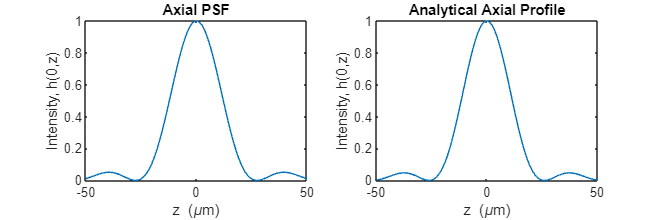

H_0z = H_xz(end/2,:);
figure;
subplot(121)
plot(z,H_0z./max(H_0z(:)))
title ('Axial numerical profile')
xlabel('z (\mum)'); ylabel('Intensity, h(0,z)');

%% compare with analitical axial profile
% on axis intensity derived in 1.2.1
H_0z_ana = sinc(pi.*z./(4*rho_a.^2*k)).^2;
subplot(122)
plot(z,H_0z_ana)
title ('Analytical profile');
xlabel('z (\mum)'); ylabel('Intensity, h(0,z)');
set(gcf,'Position', [100 100 600 200])

#### 1.2.2 3D incoherent image on a 2D imager

In order to image a 3D object, a 2D imager can capture "slices" of the object at varying image planes, $z$. The collection of these 2D images provides information from across the 3D object.

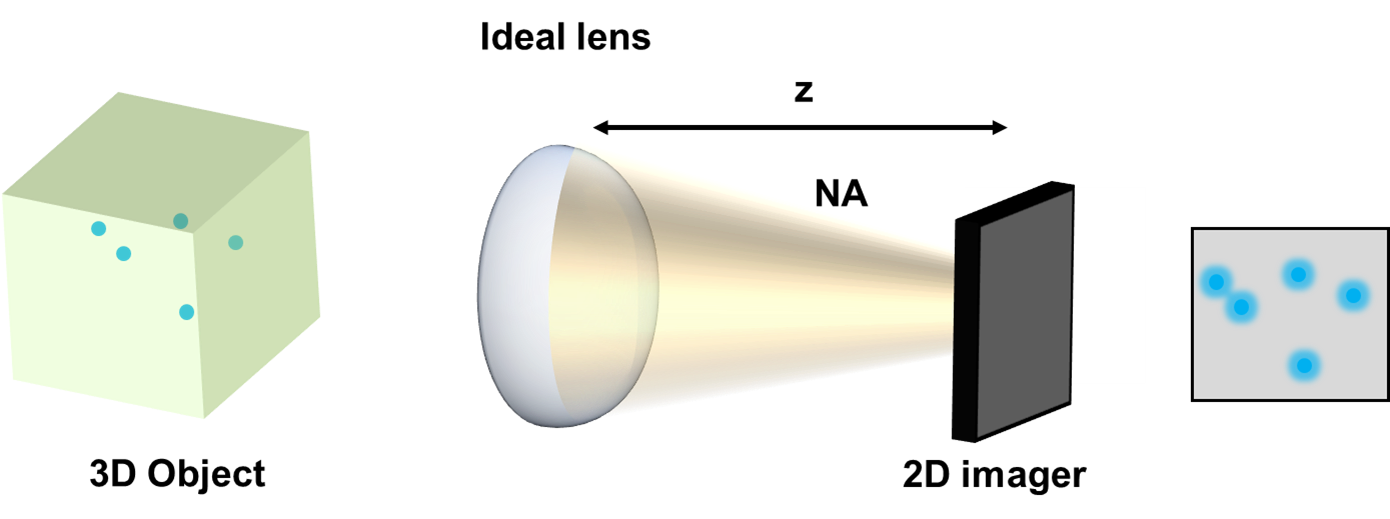

**ILL. 1.3 ***Imaging of a volumetric object using a 2D imager*

***Example 1.3***

Simulate a 2D imager to image points in a 3D object.

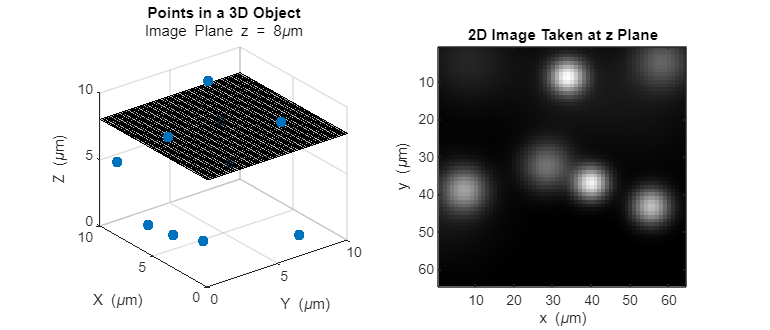

lambda = 0.632; % wavelength
NA = 0.3; % numerical aperture you can adjust
L = 10; % size of the volume [unit: um] 
nx = 64;
ny = 64;
x = linspace(0,L,nx);
y = linspace(0,L,ny);
[X, Y] = ndgrid(x,y);
w0 = lambda/(pi*NA);
zR = w0/NA;
% randomly generate several point source 
ns = 10; % number of sources in the volume
load ('L7_vol_sources.mat')

I0 = 1; % intensity amplitude of a point source

% simulate the 2D imager
z = 8; % image plane location
I = zeros(size(X));
for ii = 1:ns
    wz = w0*sqrt(1+((z-src_co(ii,3))/zR).^2);  % beam diameter
    I = I+I0*(w0./wz).^2.*exp(-((X-src_co(ii,1)).^2+(Y-src_co(ii,2)).^2)./wz.^2);
end
figure;
subplot(121)
disp_ptsz = 50;
scatter3(src_co(:,1),src_co(:,2),src_co(:,3), disp_ptsz, 'filled');
set(gcf,'Position', [100 100 700 300])
hold on
plane = zeros(64,64) +z;
surf(X,Y,plane,"FaceAlpha",0.5)
title('Points in a 3D Object',['Image Plane z = ', num2str(z),'\mum'])
xlabel('Y (\mum)'); ylabel('X (\mum)'); zlabel('Z (\mum)')

subplot(122)
imagesc(I)
title('2D Image Taken at z Plane')
xlabel('x (\mum)'); ylabel('y (\mum)'); colormap('gray')

#### 1.2.3 Optical transfer function

As discussed in Part 1, the optical transfer function (OTF) is the Fourier transform of the PSF. A narrower PSF corresponds to a broader bandwidth in spatial frequency domain. Modulation transfer function (MTF) is the magnitude of the OTF and can be measured experimentally.

For an incoherent imaging system, the point spread function is the square of the magnitude of the point spread function. Specifically, the 2D PSF at the $z$ plane, 

$h_{\textrm{inc}} \left(\rho ,z\right)=|h_{\textrm{coh}} \left(\rho ,z\right)|^2 =h_{\textrm{coh}} {\left(\rho ,z\right)}^* \cdot h_{\textrm{coh}} \left(\rho ,z\right)$,

where $h_{\textrm{coh}} {\left(\rho ,z\right)}^*$ is the complex conjugate of $h_{\textrm{coh}} \left(\rho ,z\right)$. The OTF of $H_{\textrm{inc}} \left({\mathbf{k}}_{\rho } ,z\right)$ is the the Fourier transform of $h_{\textrm{inc}} \left(\rho ,z\right)$. According to the convolution theoem,

$H_{\textrm{inc}} \left({\mathbf{k}}_{\rho } ,z\right)=H_{\textrm{coh}} {\left({\mathbf{k}}_{\rho } ,z\right)}^* \otimes H_{\textrm{coh}} \left({\mathbf{k}}_{\rho } ,z\right)$,

where $\otimes$is the convolution and $H_{\textrm{coh}} \left({\mathbf{k}}_{\rho } ,z\right)$ is the Fourier transform of the coherent PSF. Physically, $H_{\textrm{coh}} \left({\mathbf{k}}_{\rho } ,z\right)$ represents the complex-valued field on the exit pupil plane, with the image plane located at $z$. In other words, the incoherent OTF is the 2D autocorrelation of the defocused field at the exit pupil plane. Defocusing is, in fact, a $2^{\textrm{nd}}$ order aberration, introducing a parabolic wavefront.

***Example 1.4***

Plot the MTF with various level of defocus to observe that the MTF bandwidth decreases as $z$ increases, corresponding to a broader incoherent PSF.

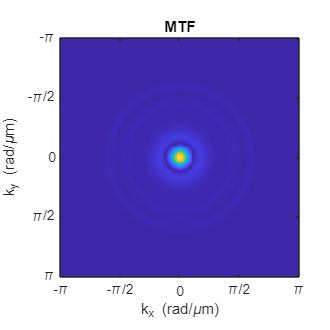

% frequency domain
% unit in um
lambda=0.632;% the wavelength [unit: um]
k = 2*pi/lambda;
NA = 0.21; % numerical aperture
rho_a = lambda/(2*NA); % freqency half-bandwidth

nx=128;
ny=128;
kx=linspace(-2*pi/2,2*pi/2,nx); % [unit: rad/um]
ky=linspace(-2*pi/2,2*pi/2,ny);
[Kx,Ky]=ndgrid(kx,ky);

hs_hat = zeros(size(Kx));
hs_hat(Kx.^2+Ky.^2<=(pi/rho_a).^2)=1; % aperture support
z = 30; % defocus [unit: um]
h_hat=hs_hat.*exp(1i.*(k-1/2.*Kx.^2./k-1/2.*Ky.^2./k).*z);

otf2d = xcorr2(h_hat);
figure;
imagesc(kx,ky,abs(otf2d))
title('MTF')
axis image;
xlabel('k_{x} (rad/\mum)'); ylabel('k_{y} (rad/\mum)')
set(gcf,'Position', [100 100 300 300])
set(gca,'XTick',-pi:pi/2:pi,'YTick',-pi:pi/2:pi) 
set(gca,'XTickLabel',{'-\pi','-\pi/2','0','\pi/2','\pi'}, ...
    'YTickLabel',{'-\pi','-\pi/2','0','\pi/2','\pi'})

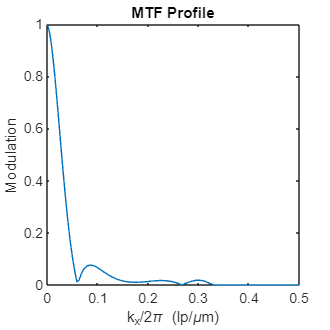

dkx=linspace(0,1/2,nx); % kx/2pi in nx steps
figure;
otf2d_pf = abs(otf2d(round(end/2):end,round(end/2)));
plot(dkx,otf2d_pf./max(otf2d_pf))
title('MTF Profile'); xlabel('k_{x}/2\pi (lp/\mum)'); ylabel('Modulation')
set(gcf,'Position', [100 100 300 300])

## 2. Image representation in 3D frequency domain

In the previous section, we have observed the 3D incoherent PSF. The 3D profile of a focus has an elongated shape, i.e., the PSF's lateral resolution is better than the axial resolution. The 2D OTF only shows the spatial bandwidth of defocused 2D PSF and could not capture the frequency information along the optical axis. 

In this section, we will perform 3D frequency analysis for a dffraction-limited lens imaging system. Similar to the discussion in frequency analysis on 3D images in previous lectures, the Fourier transform is our major tool for the analysis on three-dimensional volumetric imaging.

### 2.1 Volumetric object and 3D fourier transform

3D Fourier transform calculates the coefficients of the 3D harmonic components of a given 3D function. The 3D Fourier transform formula is as follows:


$$F\left(\mathbf{k}\right)=\underset{{\mathbf{R}}^3 }{\int \int \int } f\left(\mathbf{r}\right)e^{e^{i\cdot \;\mathbf{k}\cdot \mathbf{r}} } d\;\mathbf{r}\;$$


And the inverse Fourier transform is:


$$f\left(\mathbf{r}\right)=\frac{1}{{\left(2\pi \right)}^3 }\underset{{\mathbf{R}}^3 }{\int \int \int } F\left(\mathbf{k}\right)e^{e^{i\cdot \;\mathbf{k}\cdot \mathbf{r}} } d\;\mathbf{k}\;$$


Where $\mathbf{k}=\left\lbrack k_x ,k_y ,k_z \right\rbrack$ and $\mathbf{r}=\left\lbrack x,y,z\right\rbrack$ are spatial frequency and spatial coordinate vectors in three-dimensional space, respectively.


$$f\left(x,y,z\right)=\cos \left(k_x x+k_y y+k_z z\right)$$


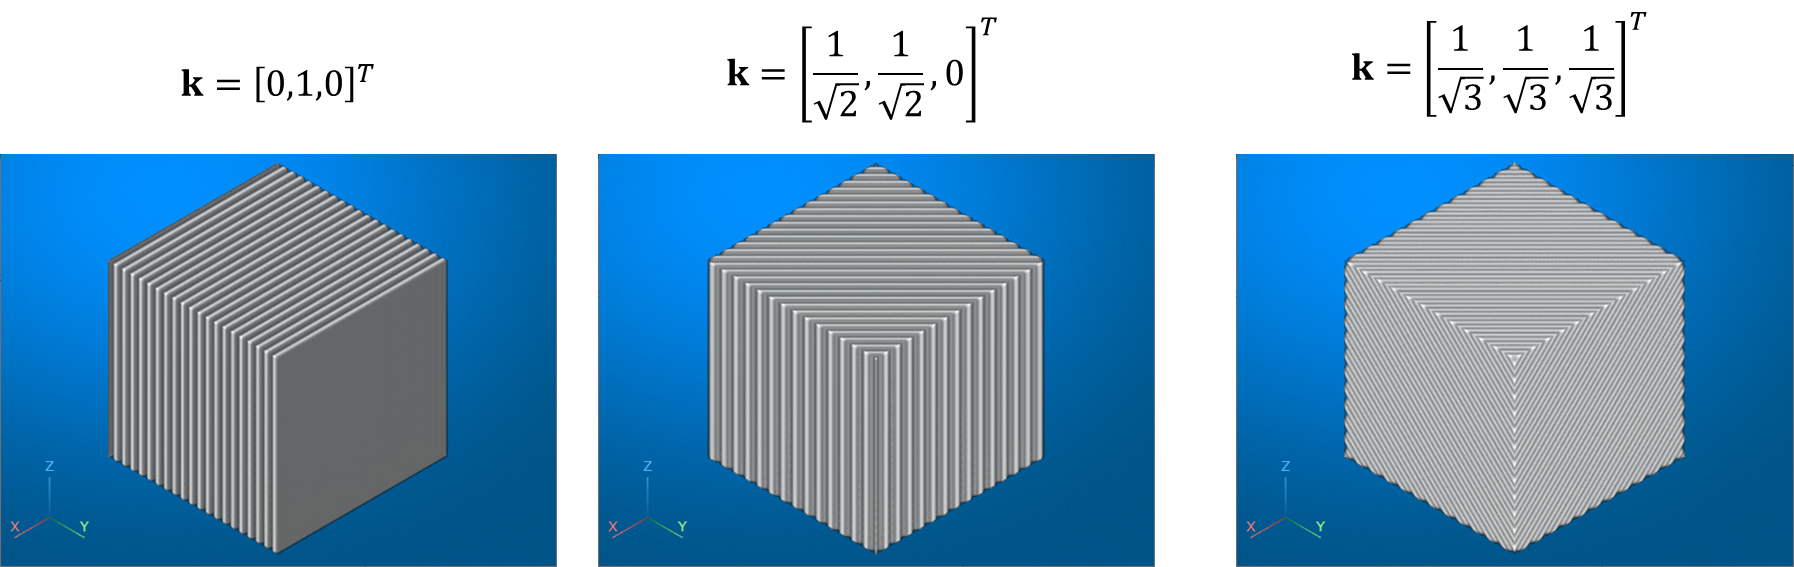

**ILL. 2.1 ***3D harmonic function*

### 2.2 Ewald sphere and OTF in 3D frequency domain

For coherent imaging in two-dimensions, each 2D spatial frequency component corresponds to a diffraction angle and collected by an ideal lens. Therefore, all 2D spatial frequency components within the frequency support can be aquired by the lens (see ILL. 2.2). This is not the case for 3D imaging, where any monochromatic wave vector is located on a 3D sphere. Therefore, only the 3D spatial frequency components on this sphere are sampled. This sphere has a radius of $k=\frac{2\pi }{\lambda }$, and is called the Ewald sphere. Similar to the 2D case, the extent of the area on the sphere that can be recieved by a lens is determined by the collection cone angle (i.e., numerical aperture).

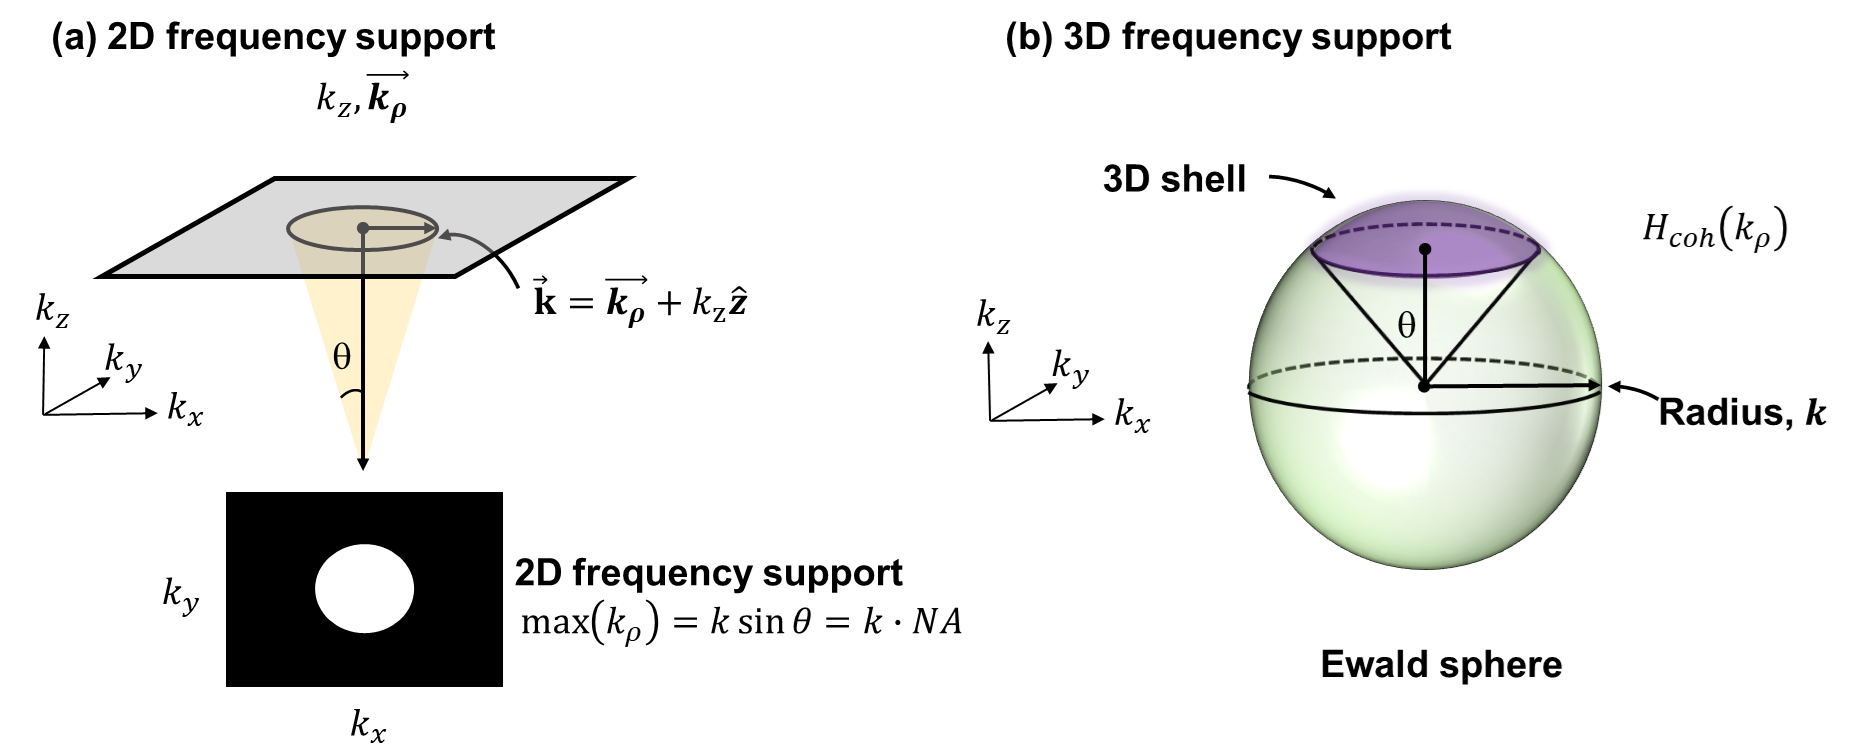

**ILL. 2.2 ***Ewald sphere and frequency support*

For incoherent imaging, the 3D PSF is the square of the magnitude of the coherent 3D PSF. Specifically,

$h_{\textrm{inc}} \left(\mathbf{r}\right)=|h_{\textrm{coh}} \left(\mathbf{r}\right)|^2 =h_{\textrm{coh}} {\left(\mathbf{r}\right)}^* \ldotp h_{\textrm{coh}} \left(\mathbf{r}\right)$,

The 3D OTF $H_{\textrm{inc}} \left({\mathbf{k}}_{\rho } ,z\right)$ is the 3D Fourier transform of $h_{\textrm{inc}} \left(\rho ,z\right)$. According to the convolution theorem,


$$H_{\textrm{inc}} \left({\mathbf{k}}_{\mathbf{r}} \right)=H_{\textrm{coh}} {\left({\mathbf{k}}_{\mathbf{r}} \right)}^* \otimes H_{\textrm{coh}} \left({\mathbf{k}}_{\mathrm{r}} \right)$$


where $\otimes$ is the convolution.

The support of the coherent OTF is


$$k_z =\sqrt{k^2 -k_{\rho }^2 },k_{\rho } \in \left\lbrack 0,k\;\sin \theta \right\rbrack$$


where $\theta$ is the half cone angle, $\textrm{NA}=\sin \theta$. The support for the 3D incoherent function in the upper half of the $k_p -k_z$ cross-section plane can be derived as


$${\left(k_{\rho } -k\;\sin \theta \right)}^2 +{\left(k_z +k\;\cos \theta \right)}^2 \le k^2 ;k_{\rho } \in \left\lbrack 0,2k\;\sin \theta \right\rbrack ,k_z \ge 0$$


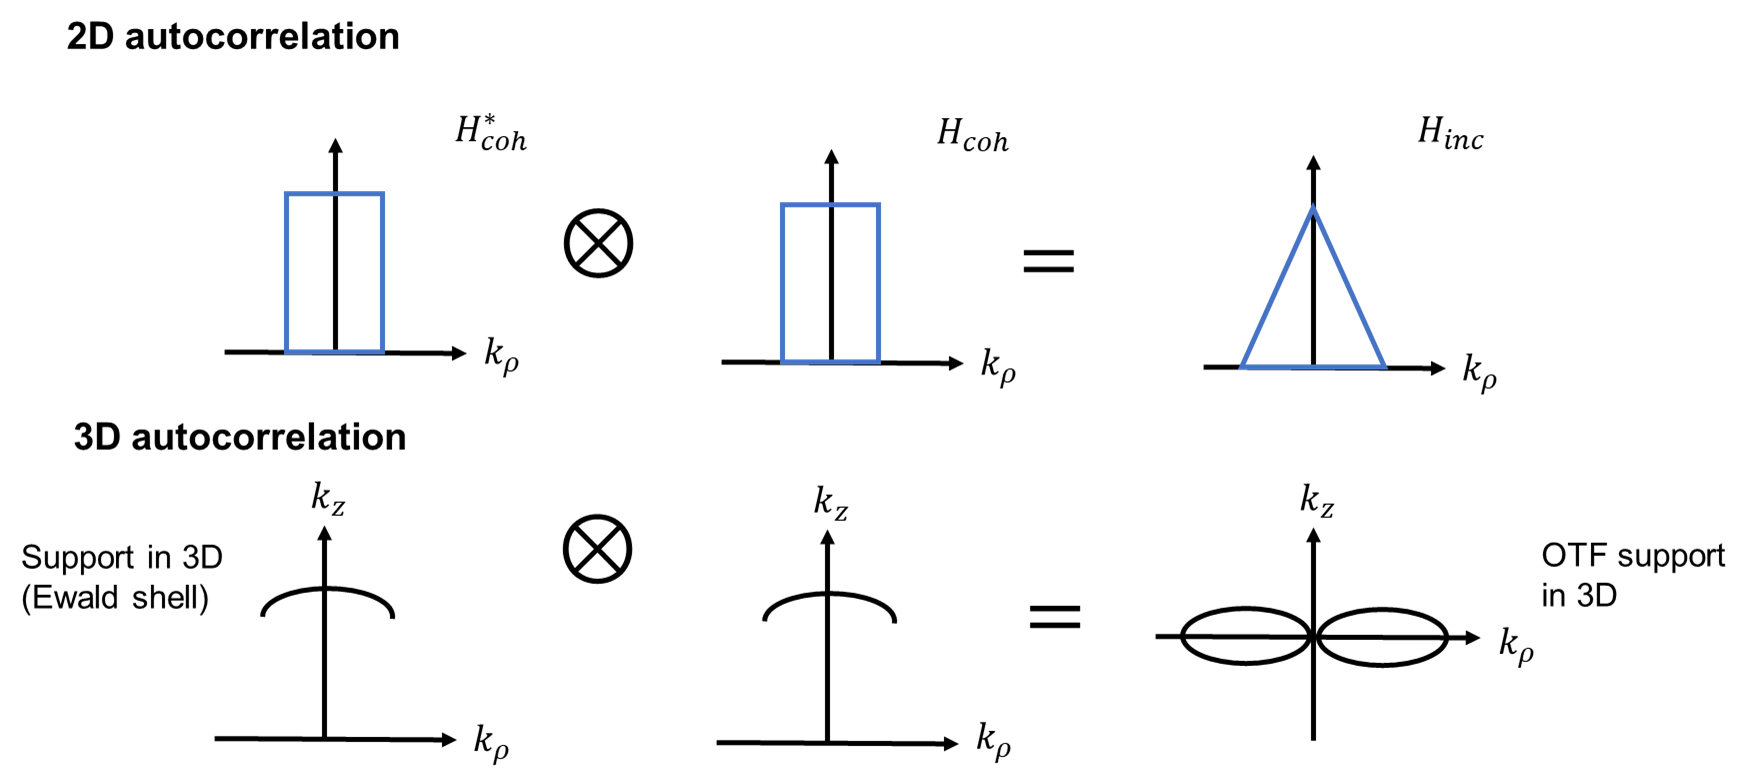

**ILL. 2.3 ***3D PSF and 3D OTF*

For a circular pupil, a compact analytical expression can be derived for the 3D OTF. The derivation is quite tedious, so we will only show the results here.


$$H\left(\mathbf{k}\right)=\frac{\textrm{NA}}{k_{\rho } }\sqrt{1-{\left(\frac{2k\cdot \left|k_z \right|}{k_{\rho } \left(k\cdot \textrm{NA}\right)}+\frac{k_{\rho } }{k\cdot \textrm{NA}}\right)}^2 }$$


***Example 2.1***

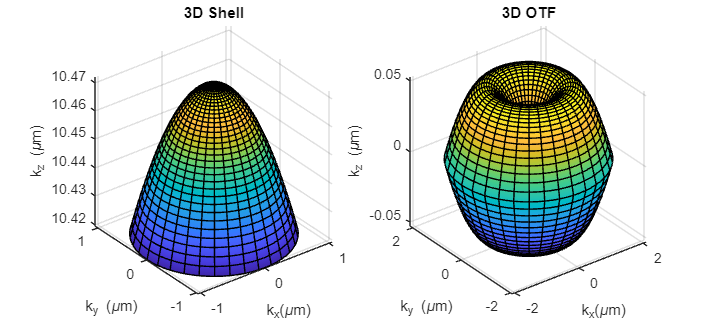

% coherent OTF support and incoherent OTF support
lambda = 0.6; % wavelength [unit: um]
k = 2*pi/lambda; % wavenumber
NA = 0.1; % numerical aperture
ks = k*NA; % sine component of the wavevector with max theta
kc = k*sqrt(1-NA^2); % corresponding cosine component.

otf_coh_x = @(theta,phi) (k.*sin(theta)).*cos(phi);
otf_coh_y = @(theta,phi) (k.*sin(theta)).*sin(phi);
otf_coh_z = @(theta,phi) k.*cos(theta);
figure()
subplot(121)
fsurf(otf_coh_x,otf_coh_y,otf_coh_z,[0 asin(NA) 0 2*pi],'-','EdgeColor','k')

title('3D Shell')
xlabel('k_{x}(\mum)')
ylabel('k_{y} (\mum)')
zlabel('k_{z} (\mum)')

otf_x = @(theta,phi) (k.*sin(theta)-ks).*cos(phi);
otf_y = @(theta,phi) (k.*sin(theta)-ks).*sin(phi);
otf_zp = @(theta,phi) k.*cos(theta)-kc;
otf_zn = @(theta,phi) -k.*cos(theta)+kc;
% OTF3D
subplot(122)
fsurf(otf_x,otf_y,otf_zp,[-asin(NA) asin(NA) 0 2*pi],'-','EdgeColor','k')
hold on
fsurf(otf_x,otf_y,otf_zn,[-asin(NA) asin(NA) 0 2*pi],'-','EdgeColor','k')

%axis equal
hold off
set(gcf,'Position', [100 100 650 300])
% add axis unit, label, title here.
title('3D OTF')
xlabel('k_{x}(\mum)')
ylabel('k_{y} (\mum)')
zlabel('k_{z} (\mum)')

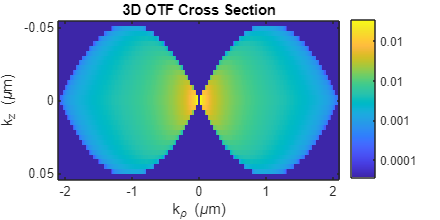

%% Display the cross-section of the OTF in log scale
n_rho = 256;
n_z = 32;
k_rho = linspace(-2*ks,2*ks,n_rho);
k_z = linspace(kc-k,k-kc,n_z);
[K_rho, K_z] = ndgrid(k_rho,k_z);
K_sup = 1-(k.*abs(K_z)./(K_rho.*ks) + K_rho./(2*ks)).^2;
H = zeros(size(K_sup));
Ind = K_sup>=0;
H(Ind) = NA./K_rho(Ind).*sqrt(K_sup(Ind));

figure()
imagesc(k_rho, k_z, log(abs(H')));
set(gcf,'Position', [100 100 400 200])
title('3D OTF Cross Section')
ylabel('k_{z} (\mum)')
xlabel('k_{\rho} (\mum)')
colorbar('TickLabels',{0.0001,0.001, 0.01, .01, 1})

### 2.3 Optical sectioning and the missing frequency

The missing cone in the OTF frequency support leads to one of the most fundamental problems in 3D imaging. Optical sectioning is the capacity of the image device to provide axial resolution for all transverse spatial frequencies within the imaging bandwidth. The capability of optical sectioning therefore is determined by the frequency support of an imaging system. For a lens-based imaging system to perform a full 3D imaging, ideally, we would hope the frequency has extended support in all directions.

However, from Section 1.2, we can see the axial resolution of the PSF is significantly lower than that in the lateral direction. Quantitatively, if we define the resolution in $z$ direction as the first zeros of the $\textrm{sinc}$ function along the $z$ direction:


$$\frac{\Delta z}{2}=\frac{4\rho_a^2 k}{\pi }=\frac{\lambda }{{\textrm{NA}}^2 }$$


Compare to the lateral resolution


$$\delta =\frac{0\ldotp 61\lambda }{\textrm{NA}}$$


Actually, comparing only the resolution, which treats the frequency component as a separate function, does not reflect the whole picture. The 3D OTF is the 3D Fourier transform of the 3D PSF. 


$$\textrm{PSF}\left(r\right)\overset{3D\;\;\textrm{FT}}{\longrightarrow} \textrm{OTF}\left(k_r \right)$$


The missing $k_z$ components are in the region of 

- missing cone at the origin along the z direction, and

- limited spatial bandwidth due to the size of the aperture, leading to $k_z$ components approaching 0 at a high lateral frequency regionn

A variety of imaging techniques have been developed to compensate the missing cone, such as sheet illumination, which we will introduce in the following chapters.